# **Household Maximization with Cobb Douglas Utility**

**Back to **[**Fan**](http://fanwangecon.github.io)**'s **[**Intro Math for Economist Table of Content**](https://fanwangecon.github.io/Math4Econ/)

## A Model with Two Goods

A consumer, with preference $U(x_1,x_2)$ and $M$ dollars, chooses between two goods, $x_1$ and $x_2$, that cost $p_1$ and $p_2$ per unit of good.

Below, we will draw the utility surface, budget set, and indifference curves.

## Model Parameters

% Number of grid points (points along x and y axis)
grid_points = 100;
% Cobb Douglas Utility
alpha = 0.5;
beta = 1-alpha;
% Budget
M = 100;
p1 = 15;
p2 = 10;
max_x1 = M/p1;
max_x2 = M/p2;

## Preference

Consumers have preference over the two goods, and $U(x_1,x_2)$ represents the utility assigned to the goods bundle $(x_1, x_2)$

If households enjoy both goods as complements, we could use this Cobb-Douglas form with Constant Return to Scale to represent the utility function:

 
$$U(x_1,x_2) = x_1^{\alpha} \cdot x_2^{1-\alpha}$$


We can use matlab to graph the utility function as a "hill":

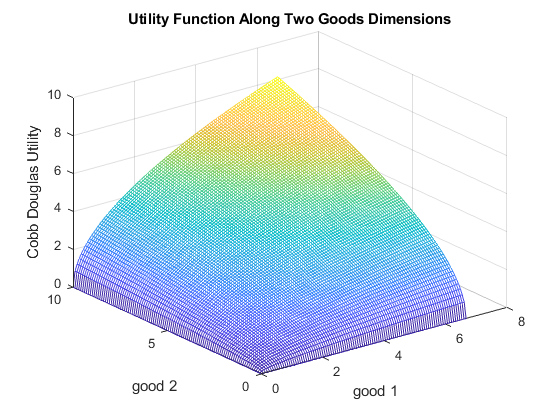

% This generates a vector between 0 and 10 with grid_points number of points
x1 = linspace(0,max_x1,grid_points);
% This generates another vector between 0 and 10 with grid_points number of points
x2 = linspace(0,max_x2,grid_points);
% This creates all possible combinations of the x1 and x2 vectors, fills up the grid
[x1mesh, x2mesh] = meshgrid(x1,x2);
% Evaluate the utility function at all x1 and x2 combination points
U = (x1mesh.^alpha).*(x2mesh.^beta);
% Graph "hill" using mesh
close all;
figure();
mesh(x1mesh,x2mesh,U);
% Labeling
xlabel('good 1');
ylabel('good 2');
zlabel('Cobb Douglas Utility');
title('Utility Function Along Two Goods Dimensions')

## Budget

The budget (choice) set facing the household could be written as:


$$B = \{ (x_1, x_2) : x_1 \ge 0, x_2 \ge 0, p_1 x_1 + p_2 x_2 \le M \}$$


where $M$ is the total resource available for the household. 

We can plot out the budget set graphically:

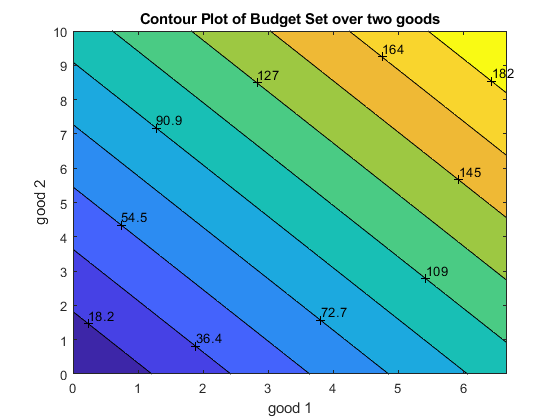

% Same as before, generating grid, and creating all possible combinations using meshgrid
x1 = linspace(0,max_x1,grid_points);
x2 = linspace(0,max_x2,grid_points);
[x1mesh_cost, x2mesh_cost] = meshgrid(x1,x2);
% Evaluate the cost of bundles of goods
bundle_cost = x1mesh_cost*p1 + x2mesh_cost*p2;
% Graph
figure();
contour = contourf(x1mesh_cost, x2mesh_cost, bundle_cost, 10);
clabel(contour);
% Labeling
xlabel('good 1');
ylabel('good 2');
zlabel('Cost');
title('Contour Plot of Budget Set over two goods')

## Budget and Preference: Indifference Curves

Budget and Utility together. Use contour plot for utility. These are the altitude graphs you have seen in your geography classes. Rather than graphing out the "hill" as earlier, we can represent the heights of the hill with contours, the show where the "hill" is higher and lower.

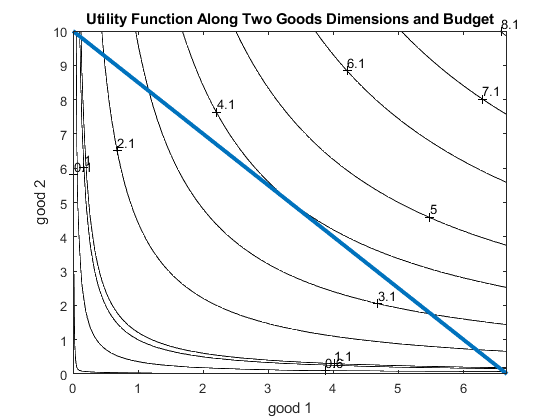

figure();
% Contour plot, the fourth parameter are at what utility values we want to see the contour lines. 
% All consumption bundle along the same contour line gives the same utility, hence they are: Indifference Curves.
contour_u = contourf(x1mesh, x2mesh, U, [0.1, 0.6, 1.1, 2.1,3.1,4.1,5,1,6.1,7.1,8.1,9.1,20,30,40,50,60,70,80,90,100]);
clabel(contour_u);
% Labeling
colormap('white')
xlabel('good 1');
ylabel('good 2');
zlabel('Cobb Douglas Utility');
title('Utility Function Along Two Goods Dimensions and Budget')
% Budget Line
% From 0 to max x1 given budget and p1
x1_M = linspace(0, M/p1, grid_points);
% Given x1 bought, what are the X2s
x2_M = (M-x1_M*p1)/p2;
hold on;
plot(x1_M, x2_M, 'LineWidth', 3);